Inputs:

clear all;
clear clf;

P_in = 68947572.8; % Pa, this is 10ksi
a = 1/32*0.0254; % m, drip hole diameter

Constants:

global P_atm roe D Q3 L dyn_visc Re f b;
P_atm = 101325; % Pa
roe = 1000; % kg/m^3
b = 5/32*0.0254; % in to m, end cap diameter
D = 0.5*0.0254; % in to m, pipe diameter
Q1 = 0.0083333*0.000063090196666667; % gal/min -> m^3/s flow near inlet, assumes that all water is flowing perfectly to the drip hole
Q2 = 0.0083333*0.000063090196666667; % gal/min -> m^3/s flow out of drip hole, this is from sweet corn estimates
Q3 = 0*0.000063090196666667; % gal/min -> m^3/s flow out of the end cap, assuming this is 0
L = 2*0.3048; % ft to m, length of pipe from pressure gauge to drip hole
dyn_visc = 0.01; %Ns/m^2
v_1 = 4*Q1/pi/D^2; % m/s this is for Re from Q1
Re = (roe)*(v_1)*(D)/(dyn_visc); % Reynold's Number (unitless)
f = 0.079*Re*exp(-0.25); % assuming turbulent flow but smooth pipe (Blasius equation)

Our equation:

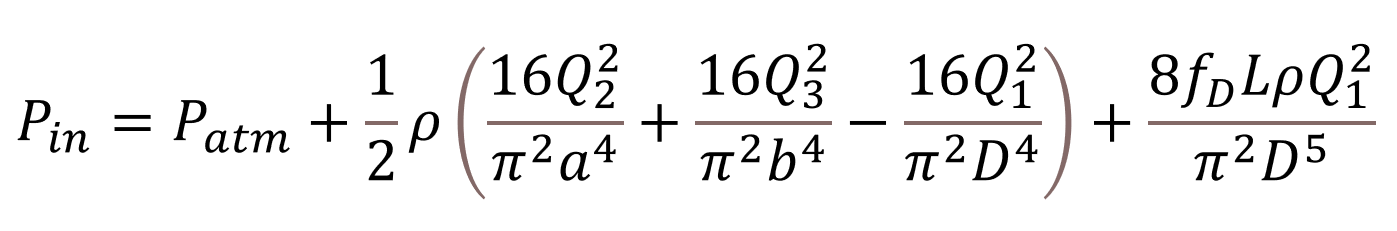

### Model 1: P inlet vs. a (drip hole diameter)

Because we're varying a, we need to re-calculate Q2. We're keeping Q2 constant, which means that v2 of the hole will change. This makes more sense than keeping the velocity constant because we're trying to deliver a certain amount of water flow, not water velocity. 

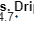

a_diameters = linspace(0.001, 0.006, 100); % m

P_in = P_atm + 0.5*roe*((16*Q2^2/pi^2./a_diameters.^4) + (16*Q3^2/pi^2/b^4) - (16*Q1^2/pi^2/D^4)) + f*L*roe*8*Q1^2/pi^2/D^5;
P_in_psi = P_in*0.00014504; %Pa -> psi

figure();
plot(a_diameters, P_in_psi)
title("Inlet Pressure vs. Drip Hole Diameter")
xlabel("Drip Hole Diameter (m)")
ylabel("Pressure (psi)")

We expect a decreasing pressure as the drip hole diameter increases.

### Model 2: P inlet vs. Q2 (drip hole flow rate)

Because we're varying P inlet to see how Q2 reacts, we need to rearrange our equation.

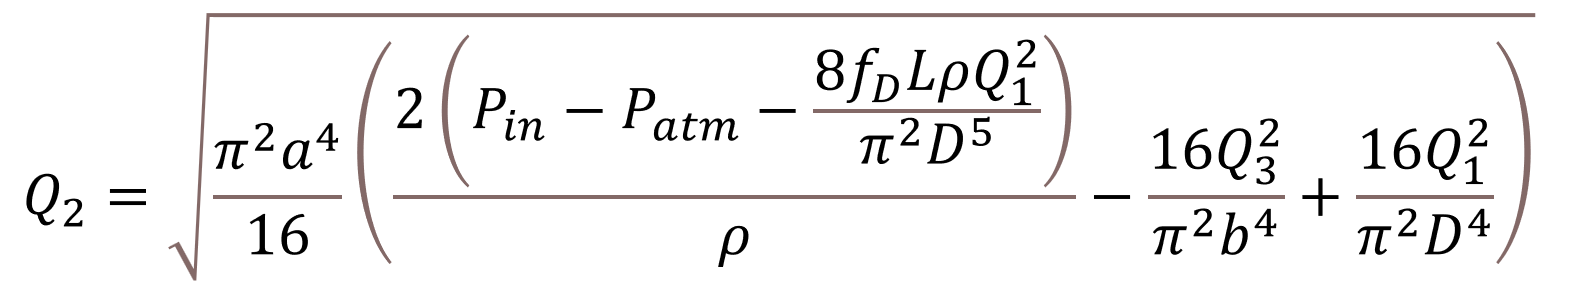

I'm converting the m^3/s units for Q2 to gals/min because it's a common way of seeing water flow units. 

Q2_plot2=sqrt((pi^2*a^4)/16 (2(P_in-P_atm-(8f_D LρQ_1^2)/(π^2 D^5 ))/ρ-(16Q_3^2)/(π^2 b^4 )+(16Q_1^2)/(π^2 D^4 )) )

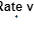

%1 m^3/s = 15850.323074494 gals/min
%1 gals/min = 1/15850.323074494 m^3/s

P_in_plot2 = linspace(1, 10, 100)*6894757.28; % ksi converted to Pa, starting from Patm in ksi
P_in_plot2_psi = P_in_plot2*0.00014504; %Pa to psi

Q2_plot2 = sqrt(pi^2*a^4/16*((2/roe*(P_in_plot2-P_atm-(8*f*L*roe*Q1^2/pi^2/D^5))) - (16*Q3^2/pi^2/b^4) + (16*Q1^2/pi^2/D^4))); %in m^3/s
Q2_plot2_gals_m = Q2_plot2*15850.323074494; %in gals/min

figure();
plot(P_in_plot2, Q2_plot2);
title("Drip Hole Flow Rate vs. Inlet Pressure")
xlabel("Inlet Pressure (psi)")
ylabel("Drip Hole Flow Rate (m^3 /s)")



friction = 8*f*L*roe*Q1^2/pi^2/D^5

friction = 0.1341

16*Q3^2/pi^2/b^4

ans = 0

16*Q1^2/pi^2/D^4

ans = 1.7225e-05

P_in_plot2-P_atm-friction

ans = 1.0e+07 *

    0.6793    0.7420    0.8047    0.8674    0.9301    0.9927    1.0554    1.1181    1.1808    1.2435    1.3061    1.3688    1.4315    1.4942    1.5569    1.6195    1.6822    1.7449    1.8076    1.8703    1.9329    1.9956    2.0583    2.1210    2.1837    2.2463    2.3090    2.3717    2.4344    2.4971    2.5597    2.6224    2.6851    2.7478    2.8105    2.8731    2.9358    2.9985    3.0612    3.1238    3.1865    3.2492    3.3119    3.3746    3.4372    3.4999    3.5626    3.6253    3.6880    3.7506


%1 m^3/s = 15850.323074494 gals/min
%1 gals/min = 1/15850.323074494 m^3/s

P_in_plot3 = 68947.5729; %Pa (10 psi)

Q2_plot2 = sqrt(pi^2*a_diameters.^4/16*((2/roe*(P_in_plot3-(8*f*L*roe*Q1^2/pi^2/D^5))) - (16*Q3^2/pi^2/b^4) + (16*Q1^2/pi^2/D^4))); %in m^3/s
Q2_plot2_gals_m = Q2_plot2*15850.323074494; %in gals/min

figure();
plot(a_diameters, Q2_plot2);
title("Drip Hole Flow Rate vs. Drip Hole Diameter")
xlabel("Drip Hole Diameter (m)")
ylabel("Drip Hole Flow Rate (m^3/s)")

## Gathering Data:

We got data for Q1, Vol2, and time_1. I need to find Q1 in terms of m^3/s, and Q2 from Vol2 and time_1. 

#### Data:

t1_a = 9/64 * 0.0254; %in -> m
t1_vol2 = [94, 114, 210, 76, 154, 260, 280, 320, 340] .* 0.000001; %ml -> m^3
t1_time2 = [2.7, 3.26, 5.6, 1.91, 4.09, 6.46, 7.57, 8.8, 9.5]; %s
t1_q1 = 1.56 * 0.0000166667; %L/min -> m^3/s
t1_pressure = 0 * 6894.75729; %psi -> Pa

t2_a = 1/8 * 0.0254; %in -> m
t2_vol2 = [60, 98, 83, 134, 169, 250, 290, 320, 192].* 0.000001; %ml -> m^3
t2_time2 = [1.9, 3, 2.47, 4.34, 5.25, 7.74, 9.15, 10.07, 3.64]; %s
t2_q1 = 1 * 0.0000166667; %L/min -> m^3/s
t2_pressure = 0 * 6894.75729; %psi -> Pa

t3_a = 7/64 * 0.0254; %in -> m
t3_vol2 = [75, 132, 88, 175, 127, 215, 340, 250, 300].* 0.000001; %ml -> m^3
t3_time2 = [2.43, 3.81, 2.56, 5.58, 4.06, 6.74, 10.5, 7.46, 9.11]; %s
t3_q1 = 0.8 * 0.0000166667; %L/min -> m^3/s
t3_pressure = 1.35 * 6894.75729; %psi -> Pa

t4_a = 3/32 * 0.0254; %in -> m
t4_vol2 = [46, 56, 85, 100, 123, 143, 120, 164, 173].* 0.000001; %ml -> m^3
t4_time2 = [2.49, 3.11, 4.79, 5.66, 6.83, 8.08, 7.45, 9.32, 10.47]; %s
t4_q1 = 7.6 * 0.0000166667; %L/min -> m^3/s
t4_pressure = 0 * 6894.75729; %psi -> Pa

t5_a = 5/64 * 0.0254; %in -> m
t5_vol2 = [28, 112, 102, 94, 75, 61, 49, 38, 32].* 0.000001; %ml -> m^3
t5_time2 = [2.48, 10.21, 9.2, 8.44, 6.78, 5.38, 4.46, 3.16, 2.84]; %s
t5_q1 = 6 * 0.0000166667; %L/min -> m^3/s
t5_pressure = 0 * 6894.75729; %psi -> Pa

### Plots

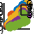

figure()
scatter(t1_time2, t1_vol2, 'filled', 'DisplayName', '9/64in'); hold on;
scatter(t2_time2, t2_vol2, 'filled', 'DisplayName', '1/8in'); hold on;
scatter(t3_time2, t3_vol2, 'filled', 'DisplayName', '7/64in'); hold on;
scatter(t4_time2, t4_vol2, 'filled', 'DisplayName', '3/32in'); hold on;
scatter(t5_time2, t5_vol2, 'filled', 'DisplayName', '5/64in'); hold on;
ylabel('Drip Hole Water Volume (m^3)');
xlabel('Time (s)')
title('Vol vs. Time by Drip Hole Diameter')
legend()

This plot shows that the volume collected increases at a relatively linear rate with time. This means we should be able to expect a scalar flow rate value for each of the pipes. 

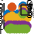


t1_q2 = t1_vol2./t1_time2;
t1_mean_q2 = mean(t1_q2);
t2_q2 = t2_vol2./t2_time2;
t2_mean_q2 = mean(t2_q2);
t3_q2 = t3_vol2./t3_time2;
t3_mean_q2 = mean(t3_q2);
t4_q2 = t4_vol2./t4_time2;
t4_mean_q2 = mean(t4_q2);
t5_q2 = t5_vol2./t5_time2;
t5_mean_q2 = mean(t5_q2);

figure() %shows variation in q2 over time
scatter(t1_time2, t1_q2, 'filled', 'DisplayName', '9/64in'); hold on;
scatter(t2_time2, t2_q2, 'filled', 'DisplayName', '1/8in'); hold on;
scatter(t3_time2, t3_q2, 'filled', 'DisplayName', '7/64in'); hold on;
scatter(t4_time2, t4_q2, 'filled', 'DisplayName', '3/32in'); hold on;
scatter(t5_time2, t5_q2, 'filled', 'DisplayName', '5/64in'); hold on;
ylabel('Drip Hole Water Volume (m^3)');
xlabel('Time (s)')
title('Q2 vs. Time by Drip Hole Diameter')
legend()

This plot shows us that the flow rate out of hte drip holes is, as expected, pretty stable. This makes sense! The only exception is an outlier for the 1/8in pipe, but other than that our data matches our expectations pretty well. 

figure() %find mean Q2, plot vs a
scatter(t1_a, t1_mean_q2, 'filled', 'DisplayName', '9/64in'); hold on;
scatter(t2_a, t2_mean_q2, 'filled', 'DisplayName', '1/8in'); hold on;
scatter(t3_a, t3_mean_q2, 'filled', 'DisplayName', '7/64in'); hold on;
scatter(t4_a, t4_mean_q2, 'filled', 'DisplayName', '3/32in'); hold on;
scatter(t5_a, t5_mean_q2, 'filled', 'DisplayName', '5/64in'); hold on;
legend();
ylabel('Drip Flow Rate (m^3/s)');
xlabel('Time (s)');
title('Mean Q2 vs time by Drip Hole Diameter')

%same plotting hole diameter vs. Q2 flow
figure() %find mean Q2, plot vs a
scatter(9/64*0.0254, t1_mean_q2, 'filled'); hold on; %in to m
scatter(1/8*0.0254, t2_mean_q2, 'filled'); hold on;
scatter(7/64*0.0254, t3_mean_q2, 'filled'); hold on;
scatter(3/32*0.0254, t4_mean_q2, 'filled'); hold on;
scatter(5/64*0.0254, t5_mean_q2, 'filled'); hold on;
ylabel('Drip Flow Rate (m^3/s)');
xlabel('Drip Hole Diameter (m)');
title('Mean Drip Flow vs. Drip Hole Diameter')

%plotting theoretical drip flow rate vs. drip hole diameter
%1 m^3/s = 15850.323074494 gals/min
%1 gals/min = 1/15850.323074494 m^3/s

P_in_plot3_1 = 1*6894.75729; %Pa (1 psi)

Q2_plot2_1 = sqrt(pi^2*a_diameters.^4/16*((2/roe*(P_in_plot3_1-(8*f*L*roe*Q1^2/pi^2/D^5))) + (16*Q1^2/pi^2/D^4))); %in m^3/s
Q2_plot2_gals_m = Q2_plot2*15850.323074494; %in gals/min

figure();
scatter(9/64*0.0254, t1_mean_q2, 'filled', 'DisplayName', '0.0036 (m^3/s)'); hold on;
scatter(1/8*0.0254, t2_mean_q2, 'filled', 'DisplayName', '0.0032 (m^3/s)'); hold on;
scatter(7/64*0.0254, t3_mean_q2, 'filled', 'DisplayName', '0.0028 (m^3/s)'); hold on;
scatter(3/32*0.0254, t4_mean_q2, 'filled', 'DisplayName', '0.0024 (m^3/s)'); hold on;
scatter(5/64*0.0254, t5_mean_q2, 'filled', 'DisplayName', '0.0020 (m^3/s)'); hold on;
plot(a_diameters, Q2_plot2_1, 'DisplayName', 'Theoretical, 10psi'); hold on;
legend();
title("Drip Hole Flow Rate vs. Drip Hole Diameter Comparison")
xlabel("Drip Hole Diameter (m)")
ylabel("Drip Hole Flow Rate (m^3/s)")

Calculated average pressure (scalar) vs. a (scalar) per trial 

t1_pressure_calc = calculated_Pin(t1_a, t1_q1, t1_mean_q2);
t2_pressure_calc = calculated_Pin(t2_a, t2_q1, t2_mean_q2);
t3_pressure_calc = calculated_Pin(t3_a, t3_q1, t3_mean_q2);
t4_pressure_calc = calculated_Pin(t4_a, t4_q1, t4_mean_q2);
t5_pressure_calc = calculated_Pin(t5_a, t5_q1, t5_mean_q2);

%---- Plotting P_in vs. a

%re-calcuting P_in using the known values of Q1 (m^3/s), Q2 (m^3/s), a (m)
a_diameters = linspace(0.001, 0.006, 100); % m
t1_P_in = zeros(1, length(a_diameters));
for i = 1:length(a_diameters)
    P_in = calculated_Pin(i, t1_q1, t1_mean_q2); %Pa
    t1_P_in(i) = P_in;
end
t2_P_in = zeros(1, length(a_diameters));
for i = 1:length(a_diameters)
    P_in = calculated_Pin(i, t2_q1, t2_mean_q2); %Pa
    t2_P_in(i) = P_in;
end
t3_P_in = zeros(1, length(a_diameters));
for i = 1:length(a_diameters)
    P_in = calculated_Pin(i, t3_q1, t3_mean_q2); %Pa
    t3_P_in(i) = P_in;
end
t4_P_in = zeros(1, length(a_diameters));
for i = 1:length(a_diameters)
    P_in = calculated_Pin(i, t4_q1, t4_mean_q2); %Pa
    t4_P_in(i) = P_in;
end
t5_P_in = zeros(1, length(a_diameters));
for i = 1:length(a_diameters)
    P_in = calculated_Pin(i, t5_q1, t5_mean_q2); %Pa
    t5_P_in(i) = P_in;
end



figure() %calculated pressure vs hole diameter
scatter(t1_a, t1_pressure_calc, 'b', 'DisplayName', '9/64in - Meas'); hold on; %Measured
plot(a_diameters, t1_P_in, '-b', 'DisplayName', '9/64in - Calc'); hold on; %Calculated
scatter(t2_a, t2_pressure_calc, 'g', 'DisplayName', '8/64in - Meas'); hold on; %Measured
plot(a_diameters, t2_P_in, '-g', 'DisplayName', '8/64in - Calc'); hold on; %Calculated
scatter(t3_a, t3_pressure_calc, 'r', 'DisplayName', '7/64in - Meas'); hold on; %Measured
plot(a_diameters, t3_P_in, '-r', 'DisplayName', '7/64in - Calc'); hold on; %Calculated
scatter(t4_a, t4_pressure_calc, 'magenta', 'DisplayName', '6/64in - Meas'); hold on; %Measured
plot(a_diameters, t4_P_in, '-magenta', 'DisplayName', '6/64in - Calc'); hold on; %Calculated
scatter(t5_a, t5_pressure_calc, 'cyan', 'DisplayName', '5/64in - Meas'); hold on; %Measured
plot(a_diameters, t5_P_in, '-cyan', 'DisplayName', '5/64in - Calc'); hold on; %Calculated
legend();
ylabel('Pressure (Pa)');
xlabel('Drip Hole Diameter (m)')
title('Inlet Pressure vs. Drip Hole Diameter')

This plot compares the theoretical pressure vs. the calculated pressure. Because we could not get accurate pressure data, the pressure was calculated using measured values of Q1, Q2, and the drip hole diameter in our pressure equation defined above. 

This plot shows us that the pressure values calculated using the measured values are about 1-2psi higher than the expected for the same diameter/q1/q2 flows. This means that our equaiton is missing some sort of major term lol (not actually lol this is sad but good that we found it). 

%---- Plotting P_in vs. average Q2
figure()
scatter(t1_pressure_calc, t1_mean_q2, 'b', 'DisplayName', '9/64in - Meas'); hold on;
scatter(t2_pressure_calc, t2_mean_q2, 'green', 'DisplayName', '1/8in - Meas'); hold on;
scatter(t3_pressure_calc, t3_mean_q2, 'red', 'DisplayName', '7/64in - Meas'); hold on;
scatter(t4_pressure_calc, t4_mean_q2, 'magenta', 'DisplayName', '6/64in - Meas'); hold on;
scatter(t5_pressure_calc, t5_mean_q2, 'cyan', 'DisplayName', '5/64in - Meas'); hold on;
ylabel('Avg. Drip Hole Flow (m^3 /s');
xlabel('Pressure (Pa)');
title('Inlet Pressure vs. Avgerage Drip Hole Flow')
legend();

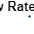

%---- Plotting P_in vs. overall Q2

%theoretical
P_in_gen = linspace(14.69594878, 20, 100)*6894.75729; % psi converted to Pa, starting from 1atm in terms of psi

t1_q2_theory = zeros(1, length(P_in_gen));
for i = 1:length(P_in_gen)
    Q2_theory = calculated_Q2(t1_a, i, t1_q1); %m^3/s
    t1_q2_theory(i) = Q2_theory;
end

figure();
plot(P_in_plot2, Q2_plot2);
title("Drip Hole Flow Rate vs. Inlet Pressure")
xlabel("Inlet Pressure (Pa)")
ylabel("Drip Hole Flow Rate (m^3/s)")

### Power

a = 3/32*0.0254;
P_atm = 101325; % Pa
roe = 1000; % kg/m^3
D = 0.5*0.0254; % in to m, pipe diameter
Q1 = 0.0083333*0.000063090196666667; % gal/min -> m^3/s flow near inlet, assumes that all water is flowing perfectly to the drip hole
Q2 = 0.0083333*0.000063090196666667; % gal/min -> m^3/s flow out of drip hole, this is from sweet corn estimates
L = 2*0.3048; % ft to m, length of pipe from pressure gauge to drip hole
dyn_visc = 0.01; %Ns/m^2
v_1 = 4*Q1/pi/D^2; % m/s this is for Re from Q1
Re = (roe)*(v_1)*(D)/(dyn_visc); % Reynold's Number (unitless)
f = 0.079*Re*exp(-0.25); % assuming turbulent flow but smooth pipe (Blasius equation)
efficiency = 0.75; %75 percent efficiency
Q_drip = Q2; %this is the desired drip rate 
total_acres = 1;
rows_per_acre = 220;
plants_per_row = 66;
g = 9.8; %m/s^2
h = 200*0.3048; %ft -> m
number_plants = rows_per_acre*plants_per_row; %total in one acre
P_headloss = 0;

P_flow = 0.5*roe*((16*Q2^2/pi^2/a^4) - (16*Q1^2/pi^2/D^4)) * plants_per_row;
Q1_total = Q_drip*plants_per_row; %m^3/s
for plant = 1:plants_per_row
    P_headloss = P_headloss + f*(L*plant)*roe*8*Q1^2/pi^2/D^5;
end
P_per_row = P_atm + P_flow + P_headloss;
P_between_rows = rows_per_acre*f*(3*0.3048)*roe*8*Q1^2/pi^2/D^5; %this is the 
P_1_acre = P_per_row*rows_per_acre + P_between_rows;
P_overall_h = P_1_acre*total_acres;

J_h = (Q1_total*P_overall_h)/efficiency; %m^3/s * Pa
J_v = (Q1_total*(P_overall_h + roe*g*h))/efficiency;

J_h;0

ans = 0

J_total = J_h + J_v; %power in kilowatts
J_h_HP = J_h*1.34102209 %horizontal power in HP

J_h_HP = 1.3934e+03

J_total_HP = J_total*1.34102209 %power in HP

J_total_HP = 2.8238e+03

### Functions

function Q2 = calculated_Q2(a_func, P_in_func, Q1_func)
    global P_atm roe D Q3 L dyn_visc Re f b;
    %constants from the script are P_atm, roe, f, L, and D
    Q2 = sqrt(pi^2*a_func^4/16*((2/roe*(P_in_func-P_atm-(8*f*L*roe*Q1_func^2/pi^2/D^5))) + (16*Q1_func^2/pi^2/D^4))); %in m^3/s

end

function P_in = calculated_Pin(a_func, Q1_func, Q2_func)
    global P_atm roe D Q3 L dyn_visc Re f b;
    %calculates a scalar value

    %constants from the script are P_atm, roe, f, L, and D
    P_in = P_atm + 0.5*roe*((16*Q2_func^2/pi^2/a_func^4) - (16*Q1_func^2/pi^2/D^4)) + f*L*roe*8*Q1_func^2/pi^2/D^5;


end